annotation_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/mean_annotators/"

annotation_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/mean_annotators/"

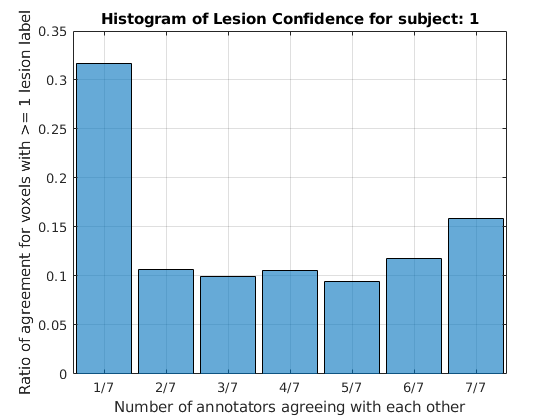

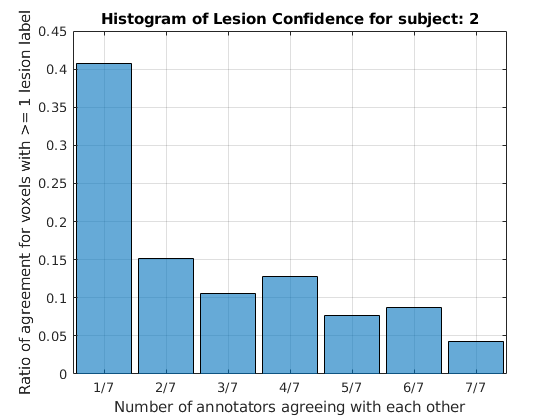

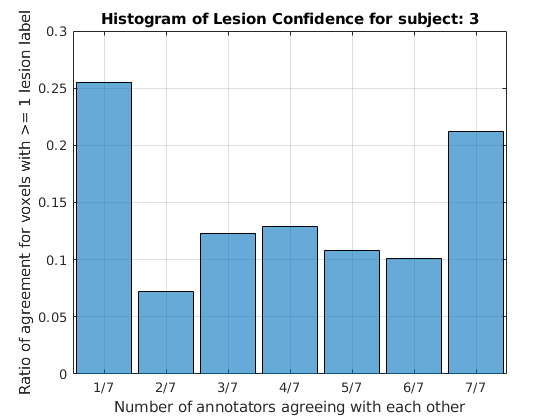

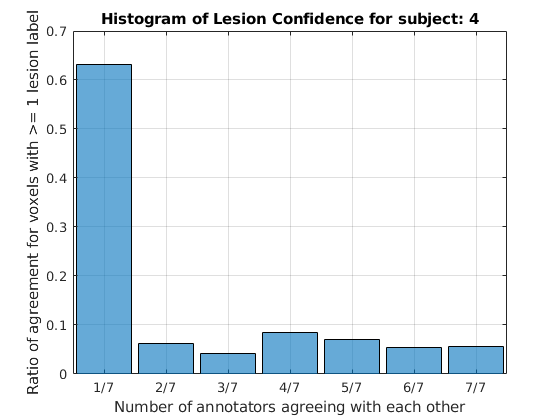

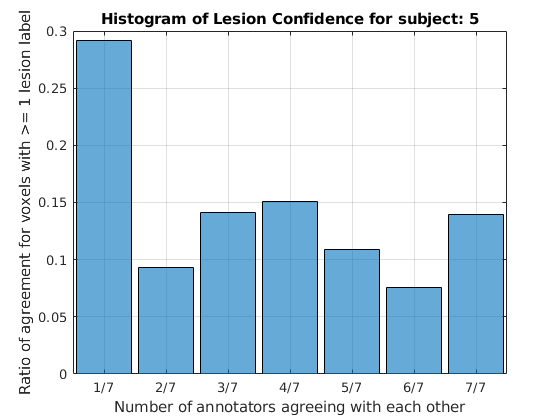

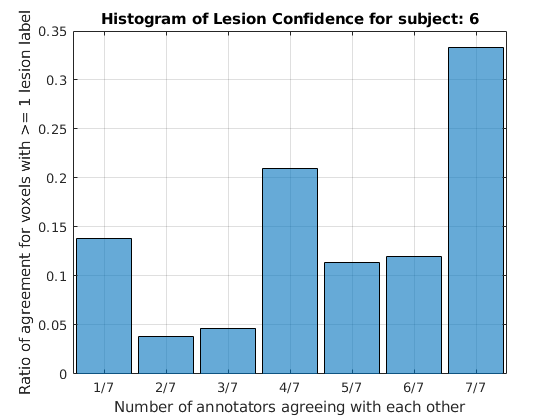

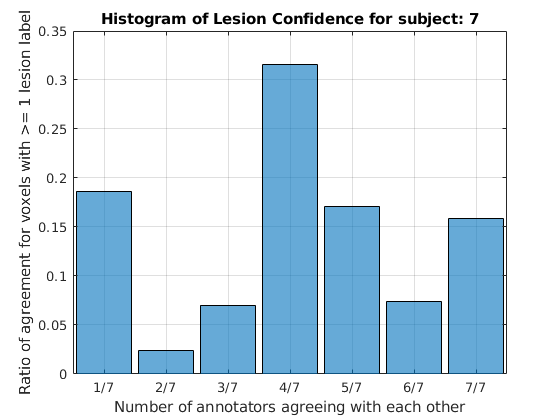

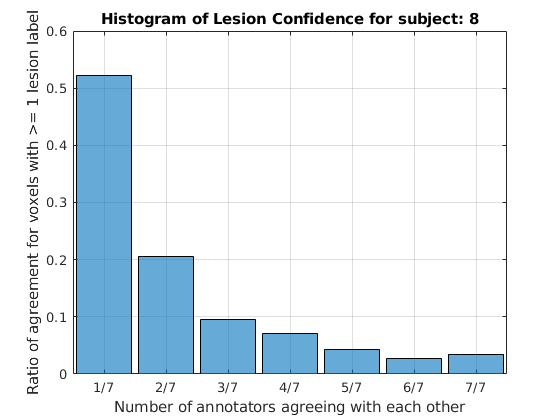


for idx = 1:24
    mean_ann_for_subject = fullfile(annotation_dir, string(idx) + "_mean_annotation.nii.gz");
    mean_data = niftiread(mean_ann_for_subject);
    mean_cat = categorical(mean_data(mean_data > 0), unique(mean_data(mean_data > 0)), ["1/7", "2/7", "3/7", "4/7", "5/7", "6/7", "7/7"]);
    figure, 
    fig = histogram(mean_cat, 'Normalization', 'probability');
    title("Histogram of Lesion Confidence for subject: " + string(idx))
    ylabel('Ratio of agreement for voxels with >= 1 lesion label')
    xlabel("Number of annotators agreeing with each other")
    grid on
    saveas(fig, fullfile(annotation_dir, string(idx) + "_histogram.png"));
end